x = 0:0.05:2*pi;
figure,
h = plot(x, tan(x), x, cot(x));
xlabel('x', 'FontSize', 12)

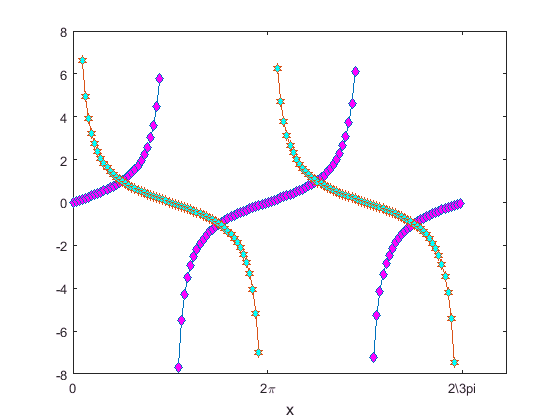

y1 = h(1).YData;
ind1 = abs(y1) > 8;
y1(ind1) = nan;
h(1).YData = y1;
y2 = h(2).YData;
ind2 = abs(y2) > 8;
y2(ind2) = nan;
h(2).YData = y2;

ha = gca;
ha.XTick = (0:2)*pi;
ha.XTickLabel = {'0', '2\pi', '2\3pi', '2pi'};
set (h(1),'Marker','diamond','MarkerFacecolor','m','Markersize',6);
set (h(2),'Marker','hexagram','MarkerFacecolor','c','Markersize',7);